Simulación de variables aleatorias 

Ejemplo 1

clear all
clc 

% Deterministic Discrete Sinusoidal Wave with Vpp=2 and offset=0
n = 0:1e3;  A=1; f0=1/50; wo= 2*pi*f0;
xn = A*cos(wo*n); % Original signal, a sine wave


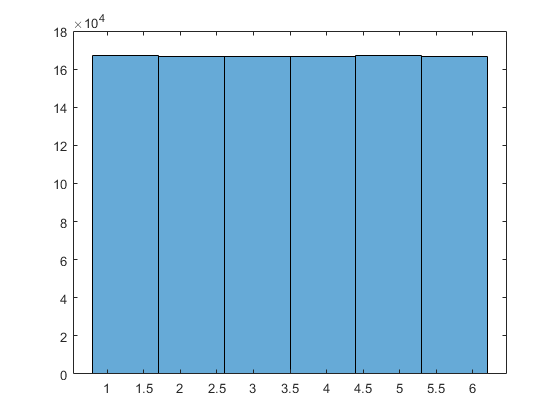

% Discrete Random variable (RV) with uniform Probability Mass Function (PMF)
xD=randi([1 6], 1,1e6);
histogram(xD,6)

mean(xD)

ans = 3.4995

var(xD)

ans = 2.9178

potencia = sum(xD.^2)/numel(xD)

potencia = 15.1642

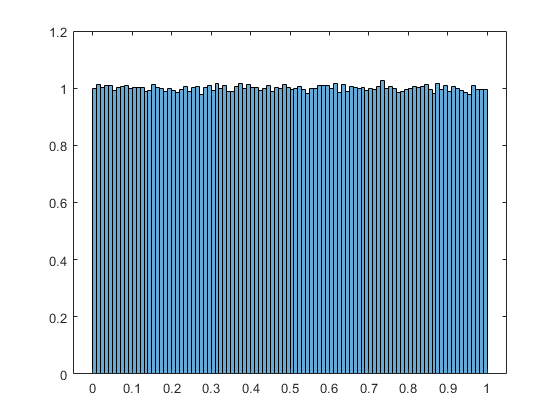


% Continuous RV with uniform Probability Density Function (PDF)
xU=rand(1,1e6);
histogram(xU,'Normalization','pdf'); % plots an estimate of the PDF for X

mean(xU)

ans = 0.4997

var(xU)

ans = 0.0833

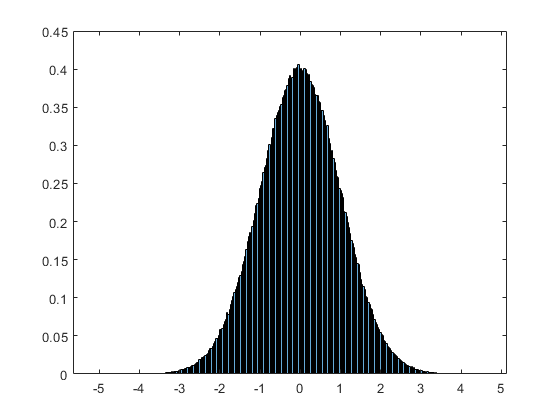


% Continuous RV with Gaussian Probability Density Function (PDF)
xG=randn(1,1e6);
histogram(xG,'Normalization','pdf'); 

mean(xG)

ans = 5.7873e-04

var(xG)

ans = 0.9994

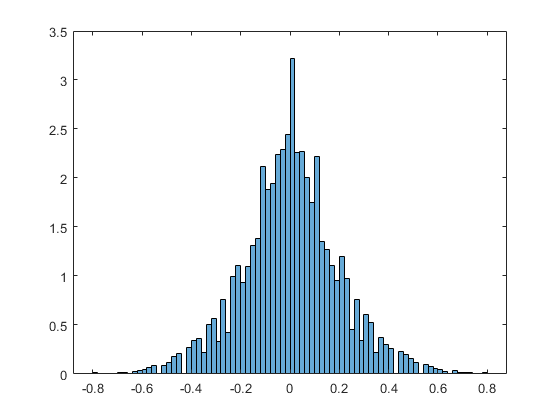

load handel.mat
histogram(y,'Normalization', 'pdf')